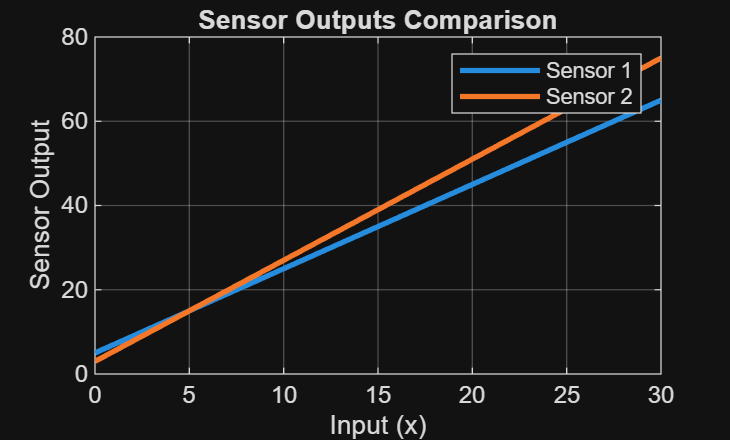

% Zulaikha Khan 
% ES 115 Engineering Computer Applications 
% Module 5 Project: Two-Sensor Calibration and Agreement Check 
% Instructor: Lynroy Grant 
% March 28, 2026 
 
clear; clc; close all; 
 
% ---------------------------- 
% Calibration points (chosen) 
 
% Sensor 1 points 
x1_pts = [0 10]; 
y1_pts = [5 25]; 
 
% Sensor 2 points 
x2_pts = [0 10]; 
y2_pts = [3 27]; 
 
% ---------------------------- 
% Compute slopes and intercepts 
 
% Sensor 1 
m1 = (y1_pts(2) - y1_pts(1)) / (x1_pts(2) - x1_pts(1)); 
b1 = y1_pts(1) - m1*x1_pts(1); 
 
% Sensor 2 
m2 = (y2_pts(2) - y2_pts(1)) / (x2_pts(2) - x2_pts(1)); 
b2 = y2_pts(1) - m2*x2_pts(1); 
 
% ---------------------------- 
% Evaluate models 
x = 0:1:30; 
 
y1 = m1*x + b1; 
y2 = m2*x + b2; 
 
% ---------------------------- 
% Plot both sensors 
figure; 
plot(x, y1, 'LineWidth', 2); hold on; 
plot(x, y2, 'LineWidth', 2); 
 
title('Sensor Outputs Comparison'); 
xlabel('Input (x)'); 
ylabel('Sensor Output'); 
legend('Sensor 1', 'Sensor 2'); 
grid on; 

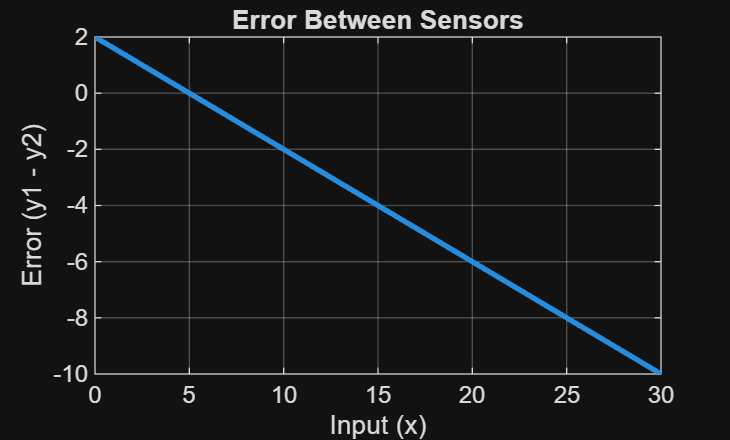

 
% ---------------------------- 
% Compute error 
e = y1 - y2; 
 
% Plot error 
figure; 
plot(x, e, 'LineWidth', 2); 
 
title('Error Between Sensors'); 
xlabel('Input (x)'); 
ylabel('Error (y1 - y2)'); 
grid on; 

 
% ---------------------------- 
% Find best agreement (minimum absolute error) 
[~, idx] = min(abs(e)); 
x_best = x(idx); 
e_best = e(idx); 
 
fprintf('Best agreement at x = %.2f with error = %.2f\n', x_best, e_best); 

Best agreement at x = 5.00 with error = 0.00
